## Problema 7

tolerances = [1e-1, 1e-2, 1e-3, 1e-4, 1e-5, 1e-6];
adquad_results = [];
romberg_results = [];

F = @(x) 2./(1+x.^2);

for tol = tolerances
    % Cuadratura adaptiva
    [Q_adquad, fcount_adquad] = adquad(F, -1, 1, tol);
    error_adquad = abs(Q_adquad - pi);
    adquad_results = [adquad_results; tol, Q_adquad, error_adquad, fcount_adquad];
    
    % Metoda Romberg
    [Q_romberg, fcount_romberg] = Romberg(F, -1, 1, tol, 10);
    error_romberg = abs(Q_romberg - pi);
    romberg_results = [romberg_results; tol, Q_romberg, error_romberg, fcount_romberg];
end

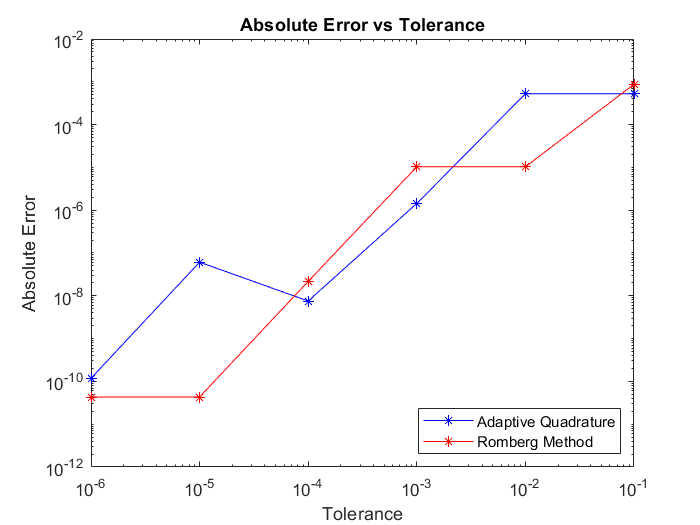

figure(1)
loglog(adquad_results(:,1), adquad_results(:,3), 'b*-');
hold on
loglog(romberg_results(:,1), romberg_results(:,3), 'r*-');
xlabel('Tolerance')
ylabel('Absolute Error')
legend('Adaptive Quadrature', 'Romberg Method', 'Location', 'southeast')
title('Absolute Error vs Tolerance')

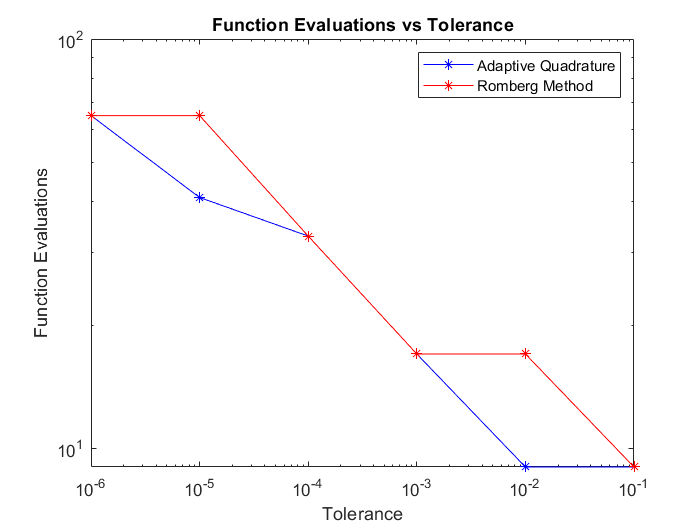

figure(2)
loglog(adquad_results(:,1), adquad_results(:,4), 'b*-');
hold on
loglog(romberg_results(:,1), romberg_results(:,4), 'r*-');
xlabel('Tolerance')
ylabel('Function Evaluations')
legend('Adaptive Quadrature', 'Romberg Method')
title('Function Evaluations vs Tolerance')

## Problema 10

a)

clear
syms x f(x) a b
R = RombergSym(f, a, b, 3);
disp(prod(factor(simplify(R(1,1)))))

$$-\frac{\left(a-b\right)\,\left(f\left(a\right)+f\left(b\right)\right)}{2}$$

disp(prod(factor(simplify(R(2,1)))))

$$-\frac{\left(a-b\right)\,\left(2\,f\left(\frac{a}{2}+\frac{b}{2}\right)+f\left(a\right)+f\left(b\right)\right)}{4}$$

disp(prod(factor(simplify(R(2,2)))))

$$-\frac{\left(a-b\right)\,\left(4\,f\left(\frac{a}{2}+\frac{b}{2}\right)+f\left(a\right)+f\left(b\right)\right)}{6}$$

SimpsonSym(f, a, b, 1)

$$ans = -\left(\frac{a}{6}-\frac{b}{6}\right)\,\left(4\,f\left(\frac{a}{2}+\frac{b}{2}\right)+f\left(a\right)+f\left(b\right)\right)$$

b)

clear
syms x f(x) a b
R = RombergSym(f, a, b, 3);
S = prod(factor(simplify(R(3, 2))))

$$S = -\frac{\left(a-b\right)\,\left(2\,f\left(\frac{a}{2}+\frac{b}{2}\right)+4\,f\left(\frac{a}{4}+\frac{3\,b}{4}\right)+4\,f\left(\frac{3\,a}{4}+\frac{b}{4}\right)+f\left(a\right)+f\left(b\right)\right)}{12}$$

% Formula lui Boole-Villarceau, din Romberg
BV = prod(factor(simplify(R(3, 3))))

$$BV = -\frac{\left(a-b\right)\,\left(12\,f\left(\frac{a}{2}+\frac{b}{2}\right)+32\,f\left(\frac{a}{4}+\frac{3\,b}{4}\right)+32\,f\left(\frac{3\,a}{4}+\frac{b}{4}\right)+7\,f\left(a\right)+7\,f\left(b\right)\right)}{90}$$

### Verificare

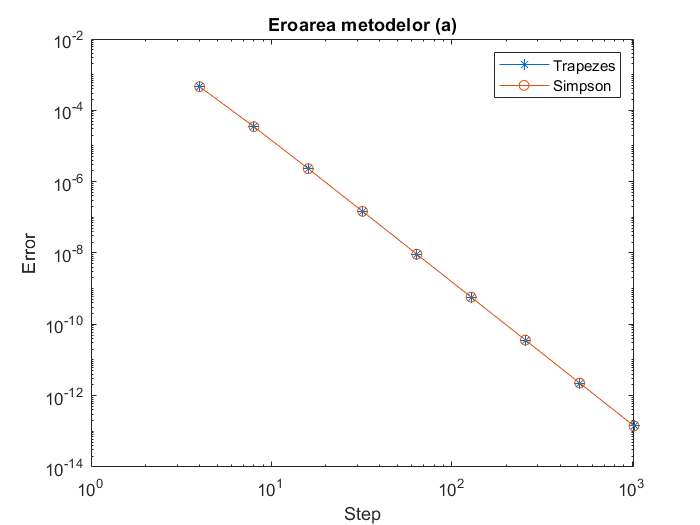

% a
clear
f = @(x) log(x);
a = 1;
b = 2;
I = integral(f, a, b);

n = 10;
steps = 2 .^ (1:n);

errors_trap = zeros(n, 1);
errors_simp = zeros(n, 1);

R = RombergSym(f, a, b, n);

for i = 2:n
    nodes_simpson = steps(i-1);
    I_Romberg = R(i, 2);
    I_Simpson = SimpsonSym(f, a, b, nodes_simpson);

    errors_trap(i) = abs(I_Romberg - I);
    errors_simp(i) = abs(I_Simpson - I);
end

clf;
loglog(steps, errors_trap, '-*', steps, errors_simp, '-o');
xlabel('Step');
ylabel('Error');
legend('Trapezes', 'Simpson');
title('Eroarea metodelor (a)');

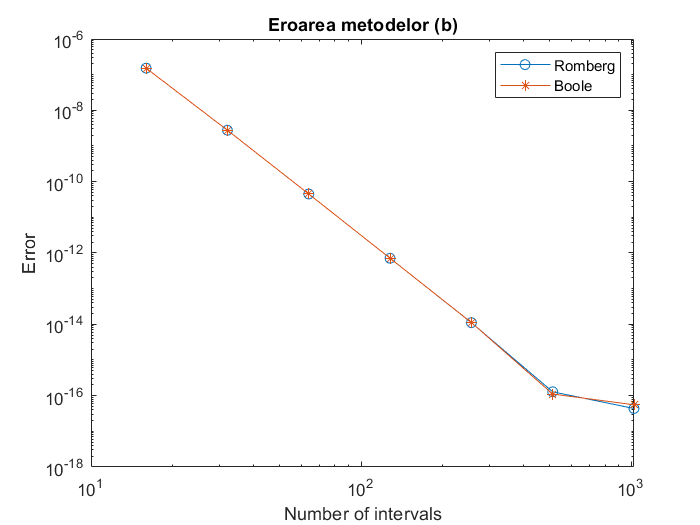

% b
clear
f = @(x) log(x);
a = 1;
b = 2;
I = 2 * log(2) - 1;

n = 10;

steps = 2 .^ (1:n);

errors_romberg = zeros(n,1); 
errors_boole = zeros(n,1);
R = RombergSym(f, a, b, n);

for i = 4:n
    nodes_boole = steps(i - 3);  

    I_Romberg = R(i, 3);
    I_Boole = BooleVillarceauSym(f, a, b, nodes_boole);

    errors_romberg(i) = abs(I_Romberg - I);
    errors_boole(i) = abs(I_Boole - I);
end

clf;
loglog(steps, errors_romberg, '-o', steps, errors_boole, '-*');
xlabel('Number of intervals');
ylabel('Error');
legend('Romberg', 'Boole');
title('Eroarea metodelor (b)');